% define xdot = Ax+Bu
% Defining symbols 
syms M m1 m2 l1 l2 g
% g = 9.81; 
A = [0 1 0 0 0 0;
     0 0 (-g*m1)/M 0 (-g*m2)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M+m1))/(M*l1) 0 -(g*m2)/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -(g*m1)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

disp(A);

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,\left(M+m_{1}\right)}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{g\,\left(M+m_{2}\right)}{M\,l_{2}} & 0 \end{array}\right)$$

B = [0;
    1/M;
    0;
    1/(M*l1);
    0;
    1/(M*l2)];
disp(B)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$

syms x x_dot theta1 theta_dot_1 theta2 theta_dot_2 F
x_t = [x;
    x_dot;
    theta1;
    theta_dot_1;
    theta2;
    theta_dot_2];
disp(x_t)

$$\left(\begin{array}{c} x\\ \dot{x}\\ \theta_{1}\\ {\dot{\theta }}_{1}\\ \theta_{2}\\ {\dot{\theta }}_{2} \end{array}\right)$$

y = expand(A*x_t+B*F)

$$y = \left(\begin{array}{c} \dot{x}\\ \frac{F}{M}-\frac{g\,m_{1}\,\theta_{1}}{M}-\frac{g\,m_{2}\,\theta_{2}}{M}\\ {\dot{\theta }}_{1}\\ \frac{F}{M\,l_{1}}-\frac{g\,\theta_{1}}{l_{1}}-\frac{g\,m_{1}\,\theta_{1}}{M\,l_{1}}-\frac{g\,m_{2}\,\theta_{2}}{M\,l_{1}}\\ {\dot{\theta }}_{2}\\ \frac{F}{M\,l_{2}}-\frac{g\,\theta_{2}}{l_{2}}-\frac{g\,m_{1}\,\theta_{1}}{M\,l_{2}}-\frac{g\,m_{2}\,\theta_{2}}{M\,l_{2}} \end{array}\right)$$

Controllability Matrix

G = [B A*B A*A*B A*A*A*B A*A*A*A*B A*A*A*A*A*B];
disp(G);

$$\begin{array}{l} \left(\begin{array}{cccccc} 0 & \frac{1}{M} & 0 & \sigma_{2} & 0 & \sigma_{1}\\ \frac{1}{M} & 0 & \sigma_{2} & 0 & \sigma_{1} & 0\\ 0 & \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{4}\\ \frac{1}{M\,l_{1}} & 0 & \sigma_{6} & 0 & \sigma_{4} & 0\\ 0 & \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{3}\\ \frac{1}{M\,l_{2}} & 0 & \sigma_{5} & 0 & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\frac{g^{2}\,m_{1}\,\left(M+m_{1}\right)}{M^{2}\,l_{1}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{2}}}{M\,l_{1}}+\frac{\frac{g^{2}\,m_{2}\,\left(M+m_{2}\right)}{M^{2}\,l_{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{M^{2}\,l_{1}}}{M\,l_{2}}\\ \sigma_{2}=-\frac{g\,m_{1}}{M^{2}\,l_{1}}-\frac{g\,m_{2}}{M^{2}\,l_{2}}\\ \sigma_{3}=\frac{\frac{g^{2}\,m_{1}\,\left(M+m_{2}\right)}{M^{2}\,{l_{2}}^{2}}+\frac{g^{2}\,m_{1}\,\left(M+m_{1}\right)}{\sigma_{7}}}{M\,l_{1}}+\frac{\frac{g^{2}\,{\left(M+m_{2}\right)}^{2}}{M^{2}\,{l_{2}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{7}}}{M\,l_{2}}\\ \sigma_{4}=\frac{\frac{g^{2}\,m_{2}\,\left(M+m_{1}\right)}{M^{2}\,{l_{1}}^{2}}+\frac{g^{2}\,m_{2}\,\left(M+m_{2}\right)}{\sigma_{7}}}{M\,l_{2}}+\frac{\frac{g^{2}\,{\left(M+m_{1}\right)}^{2}}{M^{2}\,{l_{1}}^{2}}+\frac{g^{2}\,m_{1}\,m_{2}}{\sigma_{7}}}{M\,l_{1}}\\ \sigma_{5}=-\frac{g\,\left(M+m_{2}\right)}{M^{2}\,{l_{2}}^{2}}-\frac{g\,m_{1}}{\sigma_{7}}\\ \sigma_{6}=-\frac{g\,\left(M+m_{1}\right)}{M^{2}\,{l_{1}}^{2}}-\frac{g\,m_{2}}{\sigma_{7}}\\ \sigma_{7}=M^{2}\,l_{1}\,l_{2} \end{array}$$

disp(simplify(det(G)));

$$-\frac{g^{6}\,{\left(l_{1}-l_{2}\right)}^{2}}{M^{6}\,{l_{1}}^{6}\,{l_{2}}^{6}}$$

disp(rank(G));

     6



% l1 = l2

G_subs = subs(G,l1,l2);
disp('Rank of Controllability matrix with l1 = l2');

Rank of Controllability matrix with l1 = l2


disp(rank(G_subs));

     4



M = 1000Kg, m1 = m2 = 100Kg, l1 = 20m and l2 = 10m substitute in A&B and then calculate controllability matrix

M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;
A = double(subs(A, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));
B = double(subs(B, [M, m1, m2, l1, l2, g], [M_val, m1_val, m2_val, l1_val, l2_val, g_val]));
C_= ctrb(A,B);
disp(C_);

   1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0



disp('A')

A


disp(A)

         0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5395         0   -0.0491         0
         0         0         0         0         0    1.0000
         0         0   -0.0981         0   -1.0791         0



Controllability test

if(rank(C_) == size(A))
    disp('The system is controllable');
else
    disp('The system is uncontrollable');
end

The system is controllable


Setup the system

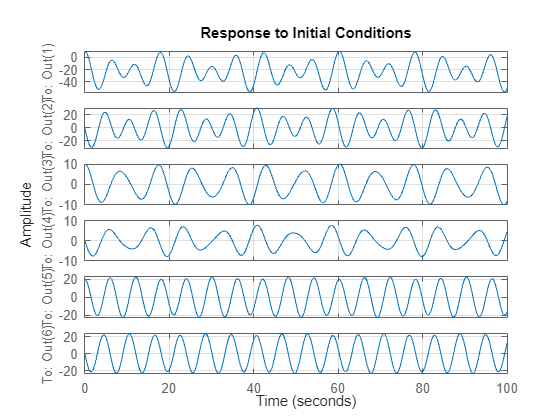

C = eye(6);
D = 0;
X_0 = [10;0;10;0;20;0];
sys = ss(A,B,C,D);
figure
initial(sys,X_0)
xlim([0,100])
grid on

LQR Controller

Q and R initialization

Q = [1000 0 0 0 0 0;  %x penalize
     0 1000 0 0 0 0;  %x_dot penalize
     0 0 1 0 0 0;   %theta1 penalize
     0 0 0 1 0 0;   %theta1_dot penalize
     0 0 0 0 1 0;   %theta2 penalize
     0 0 0 0 0 1];  %theta2_dot penalize
% Q =eye(6)*100;
R = 0.001

R = 1.0000e-03

find the value k

[k, P, ~] = lqr(A, B, Q, R)

k = 1.0e+03 *

    1.0000    1.8191   -0.2725   -0.9704   -0.1740   -0.5649


P = 1.0e+04 *

    0.1819    0.1154   -0.0970   -0.1444   -0.0565   -0.0823
    0.1154    0.2257   -0.0321   -0.4606   -0.0205   -0.2072
   -0.0970   -0.0321    3.4210    0.0470   -0.0017    0.0248
   -0.1444   -0.4606    0.0470    7.1148    0.0300    0.0781
   -0.0565   -0.0205   -0.0017    0.0300    1.3949    0.0159
   -0.0823   -0.2072    0.0248    0.0781    0.0159    1.4684


disp(k)

   1.0e+03 *

    1.0000    1.8191   -0.2725   -0.9704   -0.1740   -0.5649



[v,d] = eig(A-B*k);
disp('eigen values');

eigen values


disp(diag(d))

  -0.8198 + 0.5293i
  -0.8198 - 0.5293i
  -0.0255 + 1.0065i
  -0.0255 - 1.0065i
  -0.0117 + 0.7059i
  -0.0117 - 0.7059i



disp(real(diag(d)));

   -0.8198
   -0.8198
   -0.0255
   -0.0255
   -0.0117
   -0.0117



disp(v(:,1))

   0.7139 + 0.0000i
  -0.5853 + 0.3779i
   0.0256 - 0.0099i
  -0.0157 + 0.0217i
   0.0349 - 0.0230i
  -0.0165 + 0.0374i



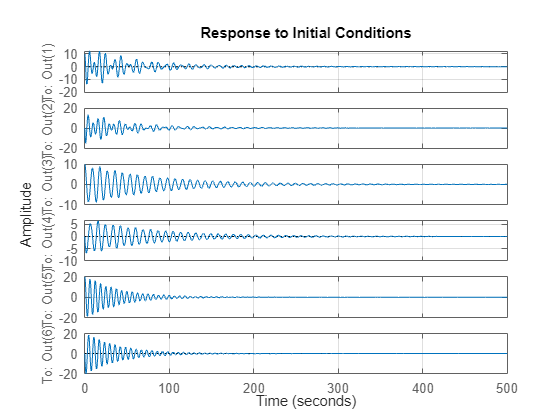

system_2 = ss(A-(B*k),B,C,D); %Using the K matrix to define ss
figure
initial(system_2,X_0)
grid on